# Image Analysis for Biometric features

Identify points in a frame that correspond the center point of a fish's head by analyzing the intensity characteristics of the larvae. The solution should not depend on threshold values that are manually determined. Investigate the accuracy of your determinations.

## Acquiring images from file

#, Perimeter,        Area, Filled Area, Solidity, Circularity, Orientation
1,    33.221,      46.000,      46.000,    0.754,       1.909,    -3.002
2,    30.062,      43.000,      43.000,    0.754,       1.672,    19.837
3,    28.929,      37.000,      37.000,    0.673,       1.800,   -85.198
4,    44.246,      69.000,      69.000,    0.742,       2.258,   -37.457
5,    30.823,      47.000,      47.000,    0.810,       1.609,   -60.000
6,    32.891,      52.000,      52.000,    0.754,       1.656,    51.681
7,    29.574,      42.000,      42.000,    0.750,       1.657,    71.829
8,    34.875,      55.000,      55.000,    0.887,       1.760,   -11.389


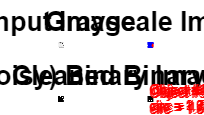

clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
imtool close all;  % Close all imtool figures.
clear;  % Erase all existing variables.
workspace;  % Make sure the workspace panel is showing.

grayfishds = imageDatastore("zebraFish\frames_grey", "FileExtensions",".png", "LabelSource","foldernames");
numImgs = length(grayfishds.Labels);

numFish = 8;
numProcessed = 0;
totalFishFound = 0;

for i = 100:100
    img = readimage(grayfishds, 1);
    grayimg = turnGray(img);
    fishFound = shapeRec(grayimg);
    totalFishFound = totalFishFound+fishFound;
%     edgeDetect(grayimg);
    numProcessed = numProcessed+1;
 end


expectedNum = numFish*numProcessed;
accuray = totalFishFound/(numFish*numProcessed)*100;
fprintf('# of Photos Processed:\t%15.0f\n# Of Fish Found:\t%15.0f\nExpected # Of Fish:\t%15.0f\nAccuracy:\t\t%14.3f%%\n', ...
    numProcessed, totalFishFound, expectedNum,accuray);

# of Photos Processed:	              1
# Of Fish Found:	              8
Expected # Of Fish:	              8
Accuracy:		       100.000%


## Convert Image to Grayscale

Despite the image already being in grayscale, matlab still considers the image an rgb even though the rgb values are all the same within each pixel. Converting the to grayscale gets rid of the rgb and allows the usage of functions that require grayscale images.

function grayimg = turnGray(img)
    grayimg = im2gray(img);
%     imshow(grayimg);
end

## Multithresh or multiotsu

Using multithresh will return a number of threshold values that will help to group regions with like intensity characteristics.

function closedhead = multiOtsu(grayimg)
    thresh = multithresh(grayimg, 11);
    
    seg_I = imquantize(grayimg,thresh);
%     figure;
    RGB = label2rgb(seg_I);
    threshedimg= im2gray(RGB);
%     imshow(threshedimg);
%     figure;
%     imshow(RGB);
%     axis off
%     title('RGB Segmented Image');
%     eyesregions = (seg_I == 1 );
%     imshow(eyesregions);
    
    headregions = ( seg_I == 1 | seg_I == 2 | seg_I == 3 | seg_I == 4 );
    
    se = strel("square",3);
    closedhead = imclose(headregions, se);
    
    closedhead = bwareaopen(closedhead, 30);
%     figure;
%     imshow(closedhead);
%     title("Cleaned heads image",'FontSize',20);
end

## Edge Detection

Using edge detection to see if it helps separate the fish from the background.

    
function edgeDetect(grayimg)
%     [~, threshOut] = edge(threshedimg, 'roberts');
    
    edgeimg = edge(grayimg, 'sobel');
    f = figure;
    f.Position = [100 100 540 400];
    imshow(edgeimg);
    
    se = strel("square",1);
    
    closedimg = imclose(edgeimg, se);
    imshow(closedimg);
    
    filledimg = imfill(closedimg, 8,'holes');
    imshow(filledimg);
    filledimg = imfill(closedimg, 8,'holes');
    imshow(filledimg);
end

## Shape Recognition demo

function fishFound = shapeRec(img)
    fishFound = 0;
    fontSize = 20;
    rgbImage = img;
    [rows, columns, numberOfColorBands] = size(rgbImage);
    % Display it.
%     figure;
    subplot(2, 2, 1); % Comment this out
    imshow(rgbImage);
    title('Input Image', 'FontSize', fontSize);
    % Enlarge figure to full screen.
    set(gcf, 'units','normalized','outerposition',[0 0 1 1]);   %comment here
%     Give a name to the title bar.
    set(gcf,'name','Shape Recognition Demo','numbertitle','off') %to here
    
    % If it's monochrome (indexed), convert it to color.
    if numberOfColorBands > 1
	    grayImage = rgbImage(:,:,2);
    else
	    % It's already a gray scale image.
	    grayImage = rgbImage;
    end
    
    % % Make a triangle on it.
    % triangleXCoordinates = [360 420 480];
    % triangleYCoordinates = [350 252 350];
    % traiangleBinaryImage = poly2mask(triangleXCoordinates, triangleYCoordinates, rows, columns);
    % % Burn it into the gray scale image.
    % grayImage(traiangleBinaryImage) = 255;
    
    % Display it.
    subplot(2, 2, 2);       %comment here down
    imshow(grayImage, []);
    title('Grayscale Image', 'FontSize', fontSize);
    
    % Binarize the image.
    binaryImage = multiOtsu(grayImage);
    % Display it.
    subplot(2, 2, 3), imshow(binaryImage);
    imshow(binaryImage, []);
    title('Initial (Noisy) Binary Image', 'FontSize', fontSize);
    
    % Remove small objects.
    binaryImage = bwareaopen(binaryImage, 30);
    % Display it.
    subplot(2, 2, 4);
    imshow(binaryImage, []);
    title('Cleaned Binary Image', 'FontSize', fontSize);
    
    [labeledImage, numberOfObjects] = bwlabel(binaryImage);
    blobMeasurements = regionprops(labeledImage,...
	    'Perimeter', 'Area', 'FilledArea', 'Solidity', 'Centroid', 'Orientation');
    
    % Get the outermost boundaries of the objects, just for fun, so we can highlight/outline the current blob in red.
    filledImage = imfill(binaryImage, 'holes');
    boundaries = bwboundaries(filledImage);
    
    % Collect some of the measurements into individual arrays.
    perimeters = [blobMeasurements.Perimeter];
    areas = [blobMeasurements.Area];
    filledAreas = [blobMeasurements.FilledArea];
    solidities = [blobMeasurements.Solidity];
    centroids = cat(1,blobMeasurements.Centroid);
    orient = [blobMeasurements.Orientation];
    % Calculate circularities:
    circularities = perimeters .^2 ./ (4 * pi * filledAreas);
    % Print to command window.
    fprintf('#, Perimeter,        Area, Filled Area, Solidity, Circularity, Orientation\n');
    for blobNumber = 1 : numberOfObjects
	    fprintf('%d, %9.3f, %11.3f, %11.3f, %8.3f, %11.3f, %9.3f\n', ...
		    blobNumber, perimeters(blobNumber), areas(blobNumber), ...
		    filledAreas(blobNumber), solidities(blobNumber), circularities(blobNumber), orient(blobNumber));
    end
    
    % Say what they are.
    % IMPORTANT NOTE: depending on the aspect ratio of the rectangle or triangle
    for blobNumber = 1 : numberOfObjects
	    % Outline the object so the user can see it.
	    thisBoundary = boundaries{blobNumber};
	    subplot(2, 2, 2); % Switch to upper right image.
	    hold on;
	    % Display prior boundaries in blue
	    for k = 1 : blobNumber-1
		    thisBoundary = boundaries{k};
		    plot(thisBoundary(:,2), thisBoundary(:,1), 'b', 'LineWidth', 3);
	    end
	    % Display this bounary in red.
	    thisBoundary = boundaries{blobNumber};
	    plot(thisBoundary(:,2), thisBoundary(:,1), 'r', 'LineWidth', 3);
	    subplot(2, 2, 4); % Switch to lower right image.
	    
	    % Determine the shape.
	    if areas(blobNumber) > 85
		    % if the blob is greater than a certain size, we can assume that
            % there are more than one fish within the blob
		    message = sprintf('For object #%d,\nthe area = %.3f,\nso the object may contain more than one fish',...
			    blobNumber, areas(blobNumber));
		    shape = 'multiple fish';
	    elseif circularities(blobNumber) > 1.4 && circularities(blobNumber) < 2.8 && areas(blobNumber) < 85
		    % Theoretical value for an isosceles triangle is (3d)^2 / (4 * pi * 0.5 * d * d * sind(60)) = 9/(4 * pi * 0.5*sind(60)) = 1.6539
		    message = sprintf('For object #%d,\nthe perimeter = %.3f,\nthe area = %.3f,\nthe circularity = %.3f,\nso the object is an isosceles triangle',...
			    blobNumber, perimeters(blobNumber), areas(blobNumber), circularities(blobNumber));
		    shape = 'fish';
            fishFound = fishFound+1;
	    else
		    message = sprintf('The circularity of object #%d is %.3f,\nso the object is something else.',...
			    blobNumber, circularities(blobNumber));
		    shape = 'something else';
	    end
	    
	    % Display the classification that we determined in overlay above the object.
	    overlayMessage = sprintf('Object #%d = %s\ncirc = %.2f, s = %.2f', ...
		    blobNumber, shape, circularities(blobNumber), solidities(blobNumber));
	    text(blobMeasurements(blobNumber).Centroid(1), blobMeasurements(blobNumber).Centroid(2), ...
		    overlayMessage, 'Color', 'r');
	    
	    % Ask the user if they want to continue
% 	    if blobNumber < numberOfObjects
% 		    button = questdlg(message, 'Continue', 'Continue', 'Cancel', 'Continue');
% 		    if strcmp(button, 'Cancel')
% 			    break;
% 		    end
% 	    end
    end
%     figure;
%     imshow(grayImage)
%     hold on
%     plot(centroids(:,1), centroids(:,2), 'rX')
%     hold off
%     fprintf();
end